## Train and test (KNN)

- Prepare the data for training

inputTable = feature_EMODB;
predictorNames = {'gtcc1', 'gtcc2', 'gtcc3', 'gtcc4', 'gtcc5', 'gtcc6', 'gtcc7', 'gtcc8', 'gtcc9', 'gtcc10', 'gtcc11', 'gtcc12', 'gtcc13', 'gtcc14', 'gtcc15', 'gtcc16', 'gtcc17', 'gtcc18', 'gtcc19', 'gtcc20', 'gtcc21', 'gtcc22', 'gtcc23', 'gtcc24', 'gtcc25', 'gtcc26', 'gtcc27', 'gtcc28', 'gtcc29', 'gtcc30'};
predictors = inputTable(:, predictorNames);
response = inputTable.Emotion;

- The model

mdl_crosscorpus = fitcknn(...
    predictors, ...
    response, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 5, ...
    'DistanceWeight', 'SquaredInverse', ...
    'Standardize', false, ...
    'ClassNames', categorical({'anger'; 'disgust'; 'fear'; 'happiness'; 'neutral'; 'sadness'}));

- Test

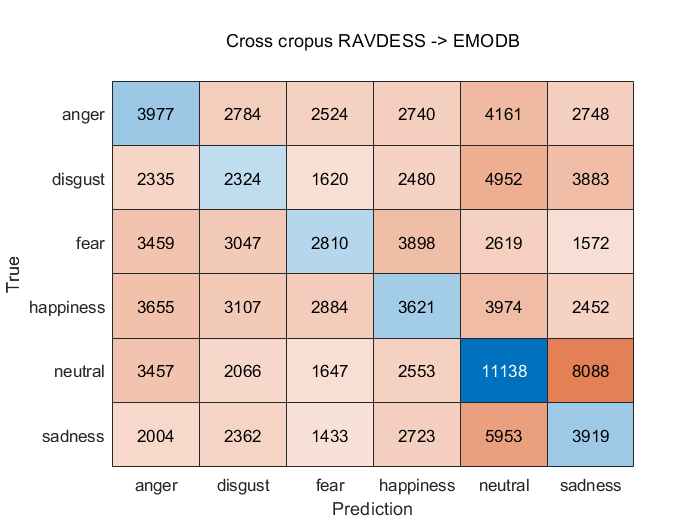

inputTable = feature_SAVEE;
predictorNames = {'gtcc1', 'gtcc2', 'gtcc3', 'gtcc4', 'gtcc5', 'gtcc6', 'gtcc7', 'gtcc8', 'gtcc9', 'gtcc10', 'gtcc11', 'gtcc12', 'gtcc13', 'gtcc14', 'gtcc15', 'gtcc16', 'gtcc17', 'gtcc18', 'gtcc19', 'gtcc20', 'gtcc21', 'gtcc22', 'gtcc23', 'gtcc24', 'gtcc25', 'gtcc26', 'gtcc27', 'gtcc28', 'gtcc29', 'gtcc30'};
predictors = inputTable(:, predictorNames);
validationResponse = inputTable.Emotion;

[validationPredictions, validationScores] = predict(mdl_crosscorpus, predictors);

correctPredictions = (validationPredictions == validationResponse);
isMissing = ismissing(validationResponse);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);

figure(1);
confusion_matrix1 = confusionchart(validationResponse,validationPredictions);
confusion_matrix1.Title = {'';'Cross cropus RAVDESS -> EMODB';''};
confusion_matrix1.YLabel = 'True';
confusion_matrix1.XLabel = 'Prediction';

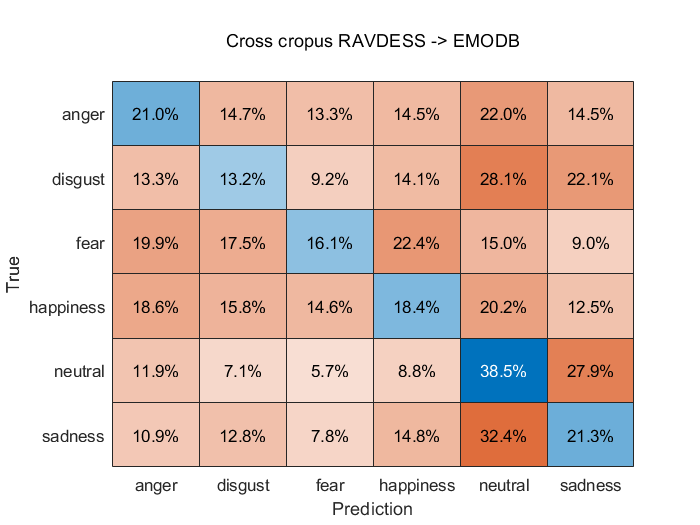


figure(2);
confusion_matrix2 = confusionchart(validationResponse,validationPredictions);
confusion_matrix2.Title = {'';'Cross cropus RAVDESS -> EMODB';''};
confusion_matrix2.YLabel = 'True';
confusion_matrix2.XLabel = 'Prediction';
% confusion_matrix2.RowSummary = 'row-normalized';
confusion_matrix2.Normalization = 'row-normalized';